clear;
currentDir = pwd;
idx = strfind(currentDir, 'chicago_crime');
if isempty(idx)
    error('Run this inside the chicago_crime folder');
end
rootFolder = currentDir(1:idx + length('chicago_crime') - 1);
addpath(genpath(fullfile(rootFolder, '..')));
dataPath = fullfile(rootFolder, ...
    'tensor_data_chicago_crime-master', ...
    'chicago_crime_2019.mat');
if ~isfile(dataPath)
    error('File not found: %s', dataPath);
end
data = load(dataPath);

F = data.X; 
A = double(full(sptensor(F.subs,F.vals,F.size)));

% HT approximation of tensor
opts.max_rank = 25;
opts.rel_eps = 1e-4;
A_ht = truncate(A,opts); 
A_htFull = full(A_ht);
norm(A_htFull - A, 'fro')/norm(A,'fro')

ans = 0.9032

Compute $\mathcal{X}_r$ for ranks $r = 1$ to $20$.

Runtime is around an hour. 

% ranks = 1:20; 
% % relErr = zeros(numel(ranks),1); 
% % tic
% % normA = norm(A,'fro'); 
% % for k = 1:numel(ranks)
% %     r = ranks(k)*ones(1,2*ndims(A_ht)-1); 
% %     X = nhtd_mu(A_ht,'rank',r,'max_it',5000,'print',false); 
% %     relErr(k) = norm(A - full(X), 'fro')/normA; 
% %     toc
% % end 
% % toc
% % 
% figure;
% plot(ranks, relErr, 'k:', 'LineWidth',1.0)
% hold on
% plot(ranks,relErr,'bx','MarkerSize',12)
% hold off
% xlabel('Rank'); ylabel('Relative Error'); 
% saveas(gcf, 'rel_error.png')

%Compute NHTD X of A
selected_rank = 7;
r = selected_rank*ones(1,2*ndims(A_ht)-1); 
X = nhtd_mu(A_ht,'rank',r,'print',false); 

Contributions of features of $U_1, U_2, U_3, U_4$

G = core_ten(X); 
cns = contributions(G); 
for i = 1:ndims(X)
    round(cns{i},2)
end

ans =     0.1300
    0.1300
    0.2000
    0.1100
    0.1500
    0.1400
    0.1400


ans =     0.1700
    0.1300
    0.1400
    0.2500
    0.0700
    0.0200
    0.2300


ans =     0.0300
    0.5800
    0.0300
    0.0500
    0.0700
    0.0200
    0.2200


ans =     0.0100
    0.0200
    0.0400
    0.1000
    0.0100
    0.1500
    0.6700


Joint rate indices between lower level features

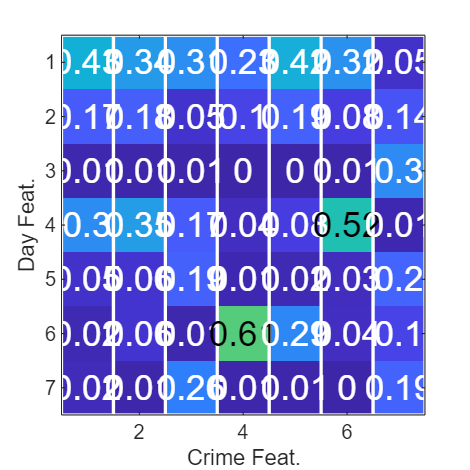

plot_mat(jr_idx(G,[1,4]),'FontSize',16)
xlabel('Crime Feat.'); ylabel('Day Feat.');
clim([0,1]); 
saveas(gcf,'jr_diagramA.jpg'); 

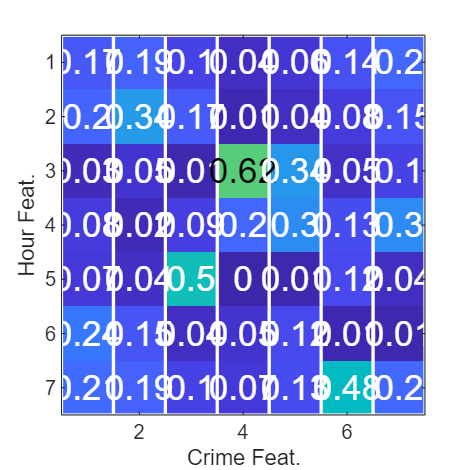


plot_mat(jr_idx(G,[2,4]),'FontSize',16)
xlabel('Crime Feat.'); ylabel('Hour Feat.');
clim([0,1]); 
saveas(gcf,'jr_diagramB.jpg'); 

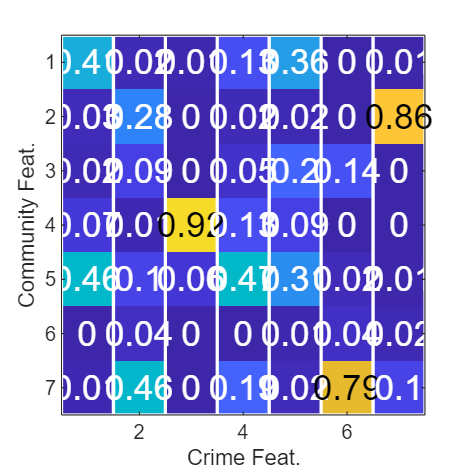


plot_mat(jr_idx(G,[3,4]),'FontSize',16)
xlabel('Crime Feat.'); ylabel('Community Feat.');
clim([0,1]); 
saveas(gcf,'jr_diagramC.jpg'); 

Plot frames

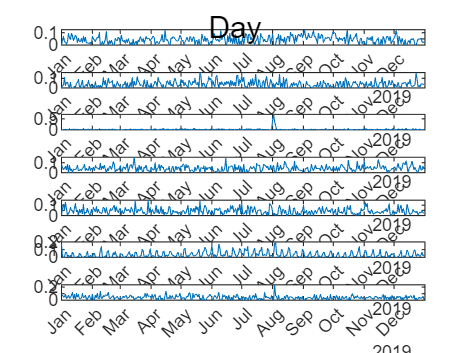

%Plot frames
U = X.U; 
U1 = U{X.dim2ind(1)}; 
   
days = 1:365;
startDate = datetime(2019,1,1);
dates = startDate + days - 1;

plot_frames(U1,'line','fixed',false, ...
    'x',dates,...
    'xticks',dateshift(dates(1), 'start', 'month') : calmonths(1) : dateshift(dates(end), 'start', 'month'))
xtickformat('MMM')
sgtitle('Day'); 
saveas(gcf,'day.jpg'); 

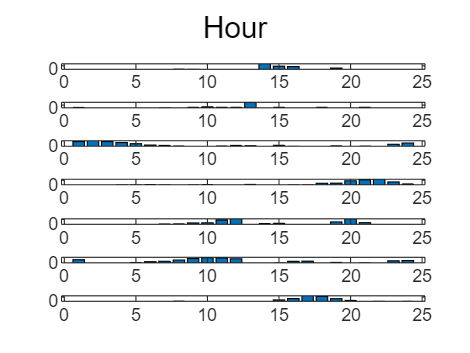


U2 = U{X.dim2ind(2)};
plot_frames(U2,'bar','fixed',false)
sgtitle('Hour'); 
saveas(gcf,'hour.jpg'); 

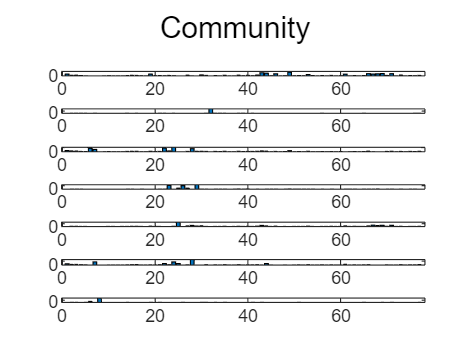


U3 = U{X.dim2ind(3)};
plot_frames(U3,'bar','fixed',false)
sgtitle('Community'); 
saveas(gcf,'community.jpg'); 

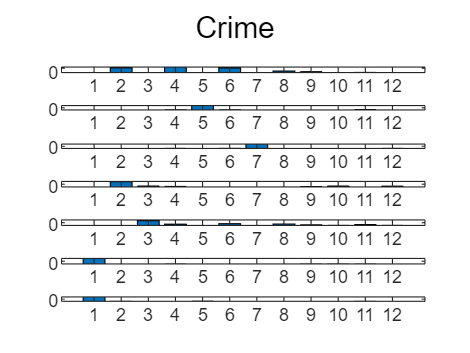


U4 = U{X.dim2ind(4)};
plot_frames(U4,'bar','fixed',false)
sgtitle('Crime'); 
saveas(gcf,'crime.jpg'); 

(Day, Hour) Features

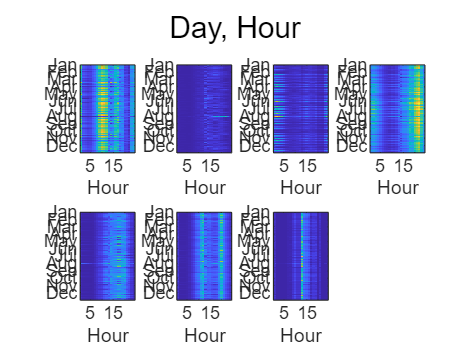

U12 = frameU(2,X); 
U12 = reshape(U12,size(X,1),size(X,2),[]);

clear days;
startDate = datetime(2019,1,1);
dates = startDate + days(0:364);
monthStarts = dateshift(dates, 'start', 'month');
[monthTicks, ~, ic] = unique(monthStarts);
monthPos = accumarray(ic, 1:length(dates), [], @min);

plot_frames(U12,'2d', ...
    'sp_sz',[2,4], ...
    'xlabel','Hour', ...
    'yticks',monthPos, ...
    'yticklabels',string(monthTicks, 'MMM'), ...
    'yes_colorbar',false, ...
    'fixed',false)
sgtitle('Day, Hour'); 
saveas(gcf,'12feat_plot.jpg')

 Line graph of (Day, Hour) Features

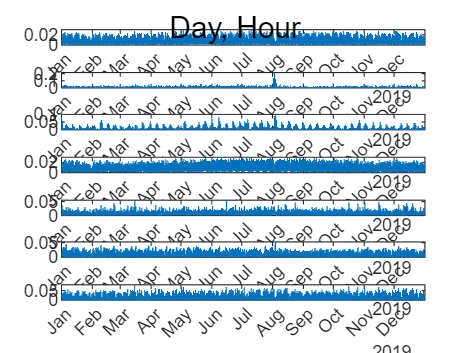

U12 = frameU(2,X); 
idx = reshape(1:size(U2,1)*size(U1,1), size(U1,1), size(U2,1))';   % swap nesting
idx = idx(:);
U12 = U12(idx, :);

t = datetime(2019,1,1,0,0,0) + hours(0:8759);   
monthTicks = dateshift(t(1), 'start', 'month') : calmonths(1) : dateshift(t(end), 'start', 'month');

plot_frames(U12,'line', ...
        'x', t, ...
        'xticks',monthTicks, ...
        'fixed',false) 
xtickformat('MMM'); 
sgtitle('Day, Hour'); 
saveas(gcf,'12feat_plot.jpg')

(Community, Crime) Features

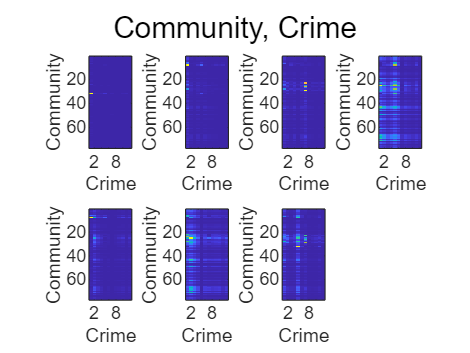

U34 = frameU(3,X);
U34 = reshape(U34,size(X,3),size(X,4),[]);
plot_frames(U34,'2d', ...
    'sp_sz',[2,4], ...
    'xlabel','Crime', ...
    'ylabel','Community', ...
    'yes_colorbar',false, ...
    'fixed',false)
sgtitle('Community, Crime'); 
saveas(gcf,'34feat.jpg')

Joint rate indices between higher level features

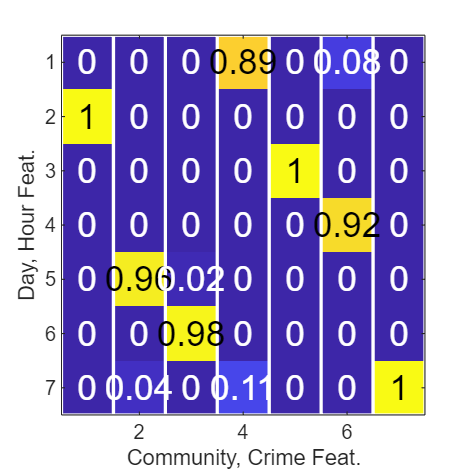

B = X.B; 
plot_mat(jr_idx(B{1},[1,2]),'FontSize',16)
xlabel('Community, Crime Feat.');
ylabel('Day, Hour Feat.'); 
saveas(gcf,'jr_diagram12_34A.jpg'); 

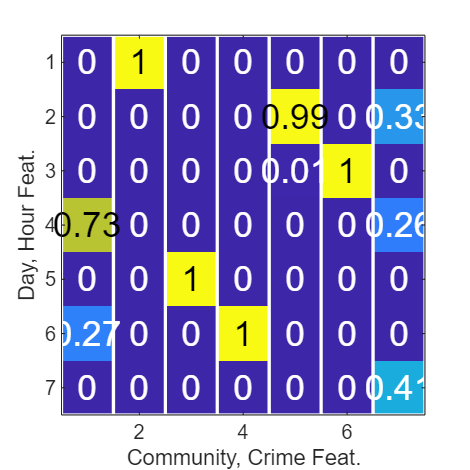


plot_mat(jr_idx(B{1},[2,1]),'FontSize',16)
xlabel('Community, Crime Feat.');
ylabel('Day, Hour Feat.'); 
saveas(gcf,'jr_diagram12_34B.jpg'); 

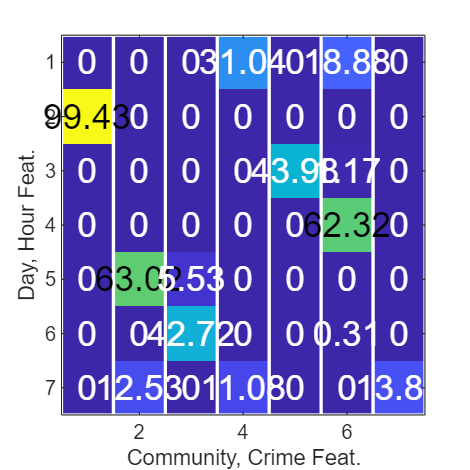


plot_mat(B{1},'FontSize',16,'threshold',50)
clim([0,100]);
xlabel('Community, Crime Feat.');
ylabel('Day, Hour Feat.'); 
saveas(gcf,'jr_diagram12_34C.jpg'); 